# DC_LAB3_AngularVelocity

addpath("plot\");
addpath("Linearization\");
addpath("Modeling\");

## 1. Obtain Static Property & Mapping Linearization  

filename='../data/Static/Static_iter';
% STEP 1. 
iter=7 % <- Modify here

iter = 7

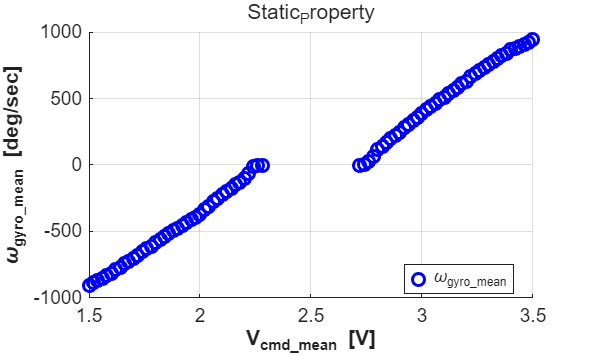

Standard Deviation: 19.7232



%1.1
[Vc, Wgyro]=plot_iter(filename, 1, 2, iter); 

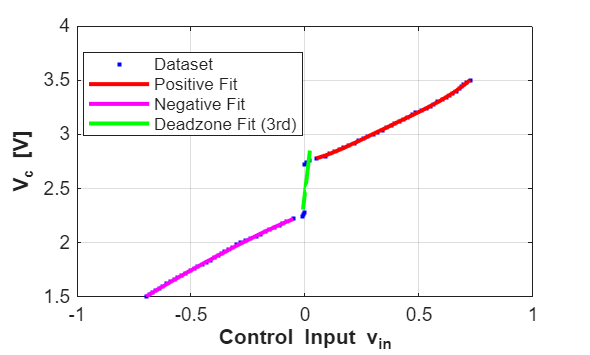


%1.2
Get_fitting_Quadratic(Vc, Wgyro); 

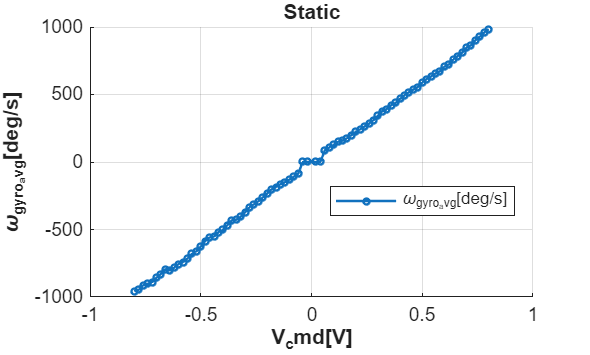


%1.3
plot_file('../data/Static_Linear/Static.out', 1, 2);

## 2. Validation - triangle

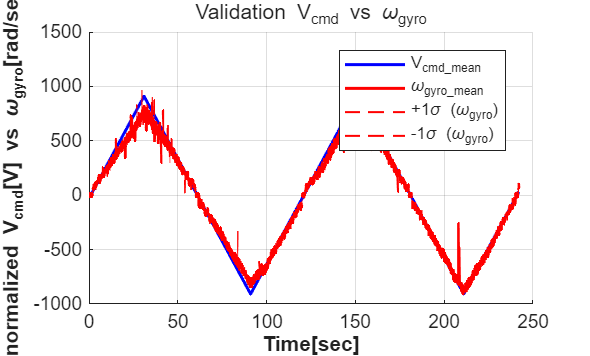

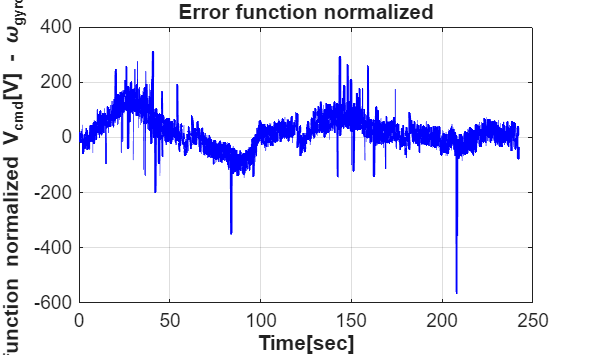

Vali_plot('tri');

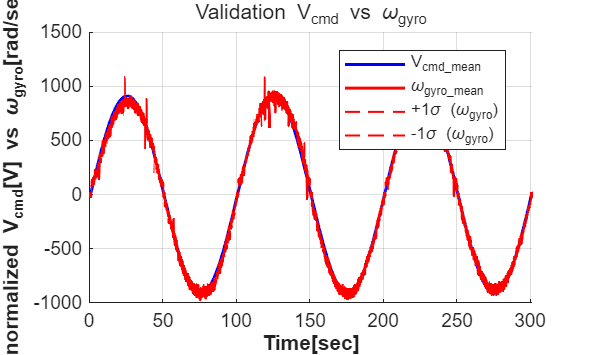

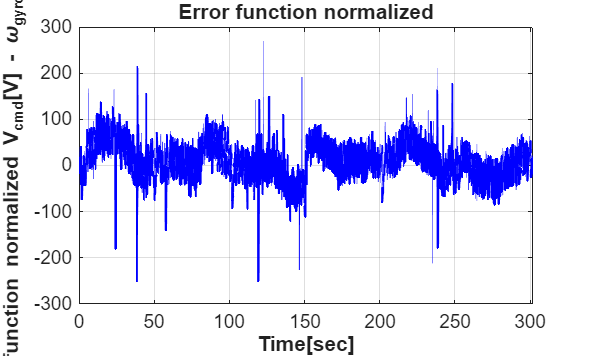

Vali_plot('sin');

## 3. Bode 

%From now on, the path is unified: 
path = '..\data\BodeMag\';

%3.1
generate_bode_plot(path);

%3.2 
plot_bode(path); 

## 4. Obtain Transfer Function  

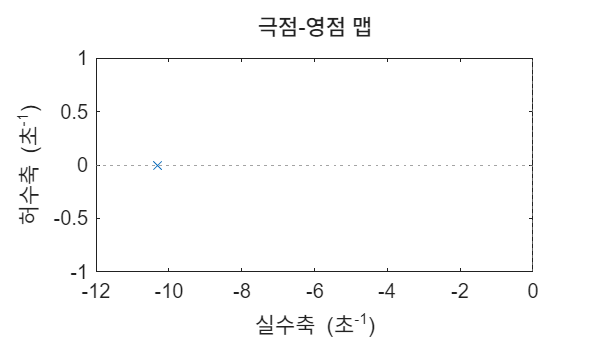


--- Identified Transf5er Function ---
 
num/den = 
 
     10.0193
   -----------
   s + 10.3045


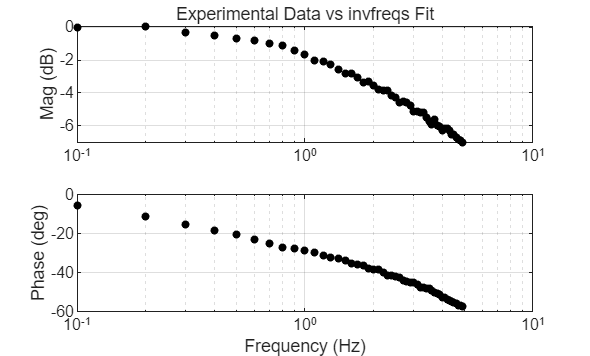

%4.1
Trans_func(path);

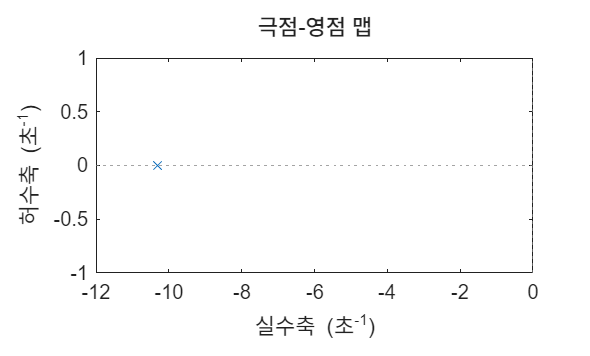


--- Identified Transf5er Function ---
 
num/den = 
 
     10.0193
   -----------
   s + 10.3045


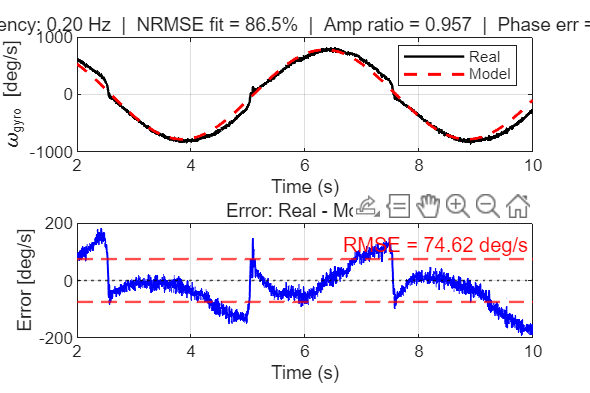

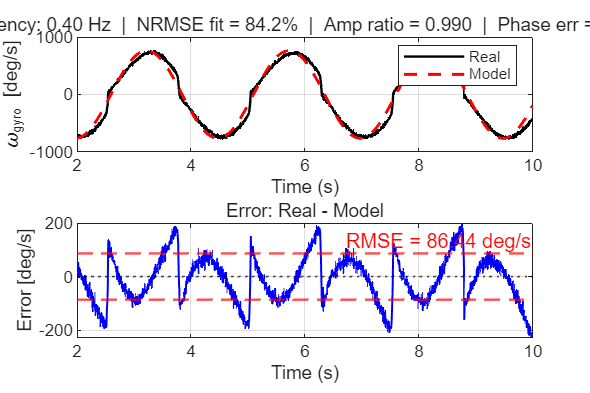

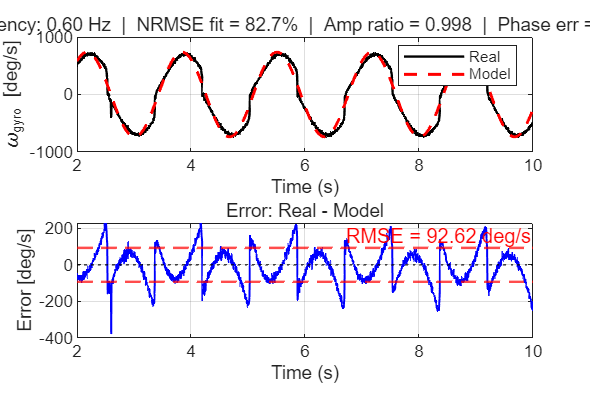

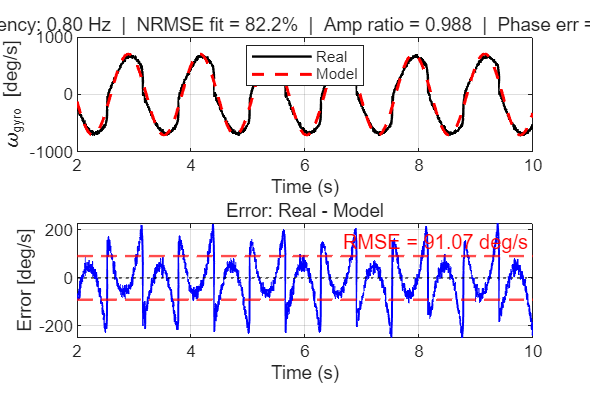

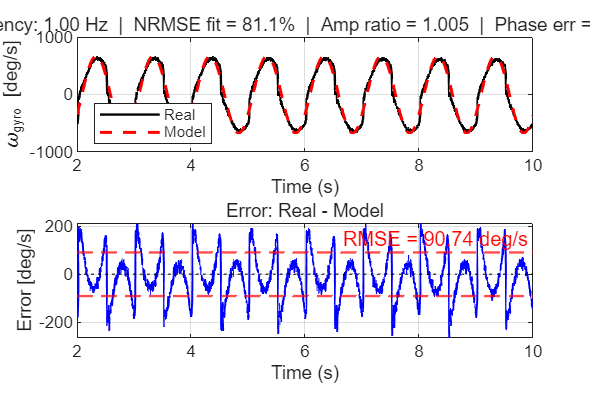

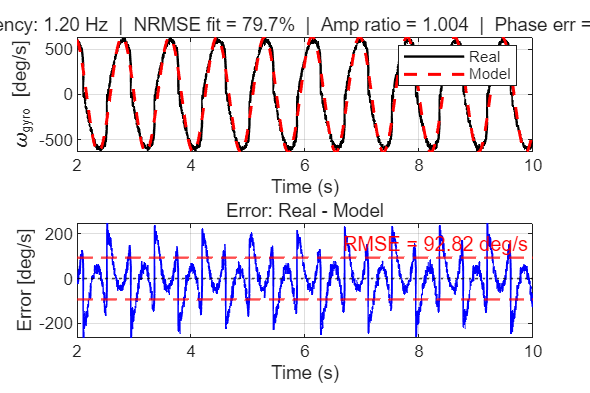

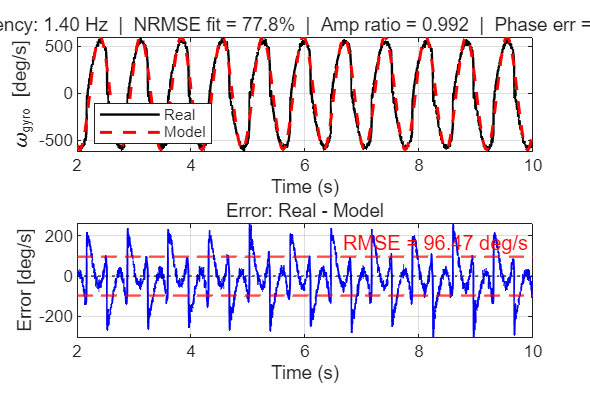

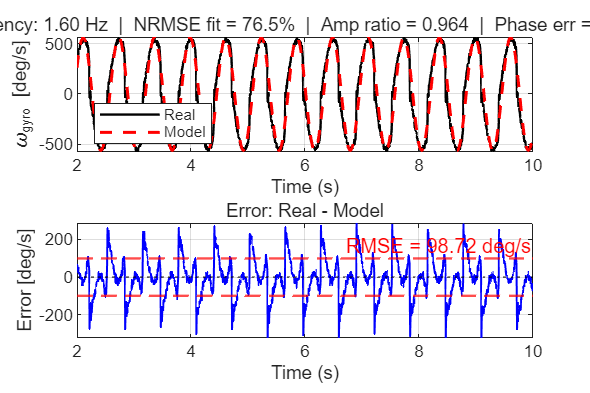


====== Validation Summary ======
Freq(Hz) RMSE       NRMSE fit%   Amp Ratio      Phase Err(deg)
------------------------------------------------------------
0.20     74.62      86.5         0.957          5.0           
0.40     86.44      84.2         0.990          4.9           
0.60     92.62      82.7         0.998          3.7           
0.80     91.07      82.2         0.988          1.3           
1.00     90.74      81.1         1.005          -2.3          
1.20     92.82      79.7         1.004          -4.5          
1.40     96.47      77.8         0.992          -7.0          
1.60     98.72      76.5         0.964          -8.5          
1.80     104.42     73.5         0.955          -11.1         
2.00     109.25     71.7         0.926          -12.2         


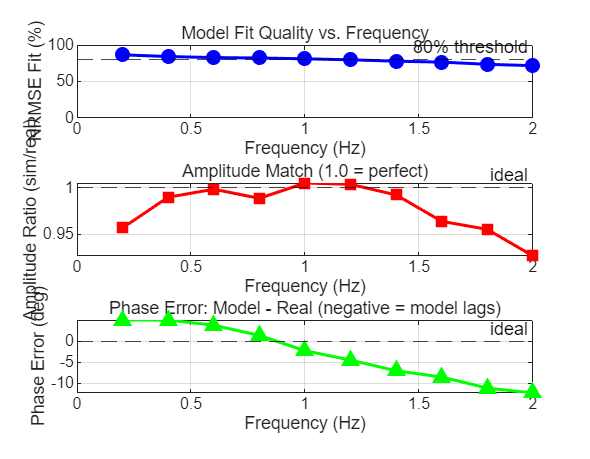

%4.2
Trans_func_valid(path); 